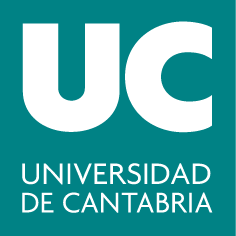

***Grado en Ingeniería en Tecnologías Industriales***

**G414: Álgebra y Geometría**

# **Operaciones con matrices**

*Sara Pérez Carabaza (sara.perezcarabaza@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es). *

**Objetivos**

- Crear vectores y matrices y acceder a sus elementos

- Operaciones básicas con matrices

**Funciones de MATLAB utilizadas en este guion: **`diag, zeros, ones, eye, size, length, det, trace, inv, sum, rref`

## 1. Definición de vectores y matrices

### 1.1 Definición** de vectores **

Para definir un vector fila usamos corchetes y separamos sus elementos por espacios o comas:

a = [1 4 9]
a = [1, 4, 9]  % podemos dejar un espacio en blanco entre números o poner una coma

Para crear un **vector columna** separamos sus elementos por ";". 

b=[1; 4; 4]

Otra opción es crear un vector fila y trasponerlo utilizando la comilla

b = [-1  2  3  5 9  11 -2]'

#### **Definición de vectores con elementos equiespacios.** 

En este caso resutan muy prácticas estas dos opciones:

- mediante el uso de ":" definimos un vector como indicando el elemento inicial, el paso y el elemento final

v1 = 1:2:10  % secuencia entre 1 y 10, que van de 2 en 2 (paso 2)

Si no indicamos el paso, MATLAB asume que el paso es 1. Por ejemplo;

v=1:10% desde 1 a 10 con paso igual a 1

- mediante el uso de la función `linspace` 

**linspace(x1,x2,N)** donde x1 es el elemento inicial, x2 el elemento final y N el número de elementos del vector

linspace(1,9,5) %vector con 5 elementos equiespaciados que van de 1 a 9

### 1.3 Definición de matrices

Para definir una matriz combinamos la definición de vector fila y vector columna. Cuando escribimos ";" es un salto de fila.  Por ejemplo:

M = [1 2 3; 4 5 6]  % matriz de 2 filas y 3 columnas
A = [1 2 1; 2 4 3; 3 5 2]  % matriz de 3 filas y 3 columnas
C=[1 2 3
4 5 6
7 8 9]%MATLAB tambiñen permite cambiar de linea de código para cambiar de fila en la definición de una matriz

### 1.4 Creación de tipos especiales de matrices: nulas, identidad y diagonales.

#### Matriz nula: `null()`

Para crear una matriz de ceros o **matriz nula** utilizamos la **función **`zeros(). `Esta toma dos argumentos de entrada, el número de filas y el número de columnas de la matriz nula.

mceros = zeros(2,3)  % matriz nula con 2 filas y 3 columnas de ceros

Si a la función ceros le pasamos un único argumento de entrada asumirá que queremos una matriz cuadrada y nos devolverá una matriz nula de esa dimensión.

zeros(3)

#### Matriz de unos: ones()

Para crear una **matriz de unos** utilizaremos la **función** `ones():`

munos = ones(2,3)  % matriz de unos con 2 filas y 3 columnas de unos

#### Matriz identidad: eye()

Para crear la **matriz identidad** utilizamos la función *eye() *a la que le pasamos el orden de la matriz:

I5 = eye(5)  % matriz identidad de orden 5

En inglés la letra I con la que se suele escribir las matrices identidad se pronuncia "eye", de ahí el nombre de la función de MATLAB.

#### Matriz aleatoria: rand()

Para crear una **matriz de números aleatorios** utilizamos la función `rand()``. Esta función genera números aleatorios entre 0 y 1 del tamaño pasado como argumento.`

maleatoria = rand(3,3)  % matriz 3x3 de números aleatorios (entre el 0 y el 1) 

Para definir una matriz diagonal podemos usar la función `diag() `pasando como argumento de entrada un vector con los elementos de la diagonal principal.

D=diag([ 1 1 3 4])

## **2. Acceso a los elementos de una matriz **

Se pueden seleccionar elementos de una matriz indicando, entre paréntesis, la posición de la fila y la columna.

A(1, 3)  % elemento de la primera fila y tercera columna

Para extraer filas o columnas enteras se utiliza el símbolo "`:`*".* Cuando escribimos  "`:`*" en las columnas estamos indicando que queremos todas las columnas.*

Por ejemplo, si queremos acceder a la 2º fila indicaremos con "`:`" que queremos acceder a todas las columnas. Obteniendo para A los elementos correspondientes a la segunda fila [$a_{2,1} ,$$a_{2,2} ,$$a_{2,3}$]

A(2, :)  % fila 2  
A(:, 1)  % columna 1 

Si queremos acceder a varias columnas a la vez podemos indicar las columnas con un vector. Por ejemplo para acceder a las dos primeras columnas:

A(:, 1:2) % columnas 1, 2. Recuerda que 1:2 genera el vector [1,2]
A(:, [1, 3]) % columnas 1 y 3

En el caso de vectores únicamente tendremos que indicar los elementos que queremos.

b(3:5)  %elementos 3 al 5 del vector columna. Recuerda que 3:5 genera el vector [3,4,5]

Para extraer la diagonal principal de una matriz usamos la función `diag()`. Ya vimos anteriormente que la función `diag` también sirve para definir una matriz diagonal. Esta función tiene distintos usos dependiendo de qué argumentos pasemos, si le pasamos una matriz nos devolverá su diagonal principipal, y si le pasamos un vector nos construirá una matriz diagonal con dicho vector en la diagonal. 

A
d = diag(A) %acceso a los elementos de la diagonal de A

## 3. Operaciones básicas con matrices: tamaño, producto matricial, traza, traspuesta, inversa.

#### Tamaño: size() y length()

Para saber cuál es el **tamaño** de una matriz usamos `size(). ``Esta función toma como argumento de entrada una matriz, y devuelve el tamaño de la matriz.`

B=[2 1 0; 7 1 2]
size(B)  % devuelve un vector con el tamaño de la matriz (filas y columnas) 

Si queremos guardar el número de filas y columnas de B utilizamos corchetes separados por comas. Esta es la forma de guardar los argumentos de salida de una función de MATLAB con más de un argumento de salida.

[nf,nc]=size(B)

En el caso de un vector, podemos comprobar su longitud con la función `length``()`:

v = [5 6 -5 1 0];
size(v)
length(v)  % número de elementos en un vector fila

#### Producto matricial

El **producto matricial** de dos matrices se realiza como  **A*B**

Por ejemplo Sean $A$ y $B$ dos matrices tales que:

A = ones(3,3)*2
B = ones(3,3)*4%multiplicamos matriz 3x3 de unos por el escalar 4
A*B  % producto matricial

#### Producto elemento a elemento

También podemos **multiplicar dos matrices de las mismas dimensiones elemento a elemento **usando **"**`.*`**"**. En esta asignatura de manera general trabajaremos con el producto matricial, y no con el producto elemento a elemento:

A.*B  % producto elemento a elemento 

#### Trasposicíón

Para **transponer** una matriz:

B' % traspuesta de B

#### Determinante

Cálculo del **determinante** de una matriz mediante la función `det()`

det(A)   % determinante de la matriz A

#### Traza

Cálculo de la **traza** de una matriz mediante la función `trace`**()**

trace(A)

#### Matriz inversa

Cálculo de la matriz **inversa **mediante la función `inv()`

C=[1 2 4; 2 0 1; 0 0 1]
inv(C)
C*inv(C)%comprobamos que obtenemos la matriz identidad

Ten cuidado con no calcular inversas de matrices singulares

inv(A)  % inversa de la matriz A
det(A)% ojo recuerda que si el determinante es cero, la matriz es singular y no tiene inversa

#### Suma de los elementos de una matriz: sum()

Otra función de MATLAB que resulta muy útil es la función `sum()`, esta permite sumar elementos.

Si a la función `sum` le pasamos un vector (ya sea fila o columna) nos devolverá la suma de todos sus elementos.

v=[1 1 2 1];
sum(v)
A=[1 -1 1
   1  1 2];
sum(A)% al aplicar sum sobre una matriz, se obtiene un vector con la suma de las columnas de A

#### Rango de una matriz: rank()

La función `rank()` toma como argumento de entrada una matriz, y nos devuelve su rango

rank(A)
I=eye(3);
rank(I)

#### Obtener matriz escalonda reducida equivalente por filas (método Gauss): rref()

La función `rref()` permite calcular la forma escalonada reducida por filas de una matriz, equivalente al resultado de aplicar el método de Gauss-Jordan.

Ared=rref(A) % la matrize escalonada reducida Ared tiene 2 pivotes -> A tiene rango 2

## 4. Concatenación de matrices

Podemos definir una matriz concatenando dos o más matrices. 

El siguiente ejemplo concatena el vector v=[ 1 2 3] a la derecha de la matriz identidad de orden 3, guardando el resultado en la matriz B. Para poder concatenar a la derecha de la matriz identidad una matriz/vector este deberá tener dimensiones adecuadas (3 filas).

v=[1 2 3]
B=[eye(3) v']%concatenamos un vector columna

Ahora concatenaremos debajo de la matriz B el siguiente vector w=[1 2 3 4]. Para concatenar "debajo" indicaremos con ";" el salto de fila. La matriz resultante la guardaremos en C.

w=[1 2 3 4] %vector fila
C=[B ; w] %concatenamos el vector fila w

## Bibliografía 

- Guiones para Matlab realizados por Rodrigo García Manzanas y Ruth Carballo Fidalgo para la asignatura de Álgebra y Geometría del Grado en Ingeniería Civil.